% f = ?
% y'= z
f = @(t,y) [y(2); 0.15*y(1)];
a=0;
b=10;
ya=240;
yb=150;
h=0.01;
d = shootingF(f,a,b,ya,yb,h,-90.6)

d = -0.2136

d = shootingF(f,a,b,ya,yb,h,-90.59)

d = 0.4023


g = @(s) shootingF(f,a,b,ya,yb,h,s);
g(-90.6)

ans =   -0.213636229718873


g(-90.59)

ans =    0.402253538468528


[s, i] = biseccion(g,-90.59,-90.6)

s =  -90.596531258664186


i =     39


y0= [ya;s]

y0 = 	1.0e+02 *

   2.400000000000000
  -0.905965312586642


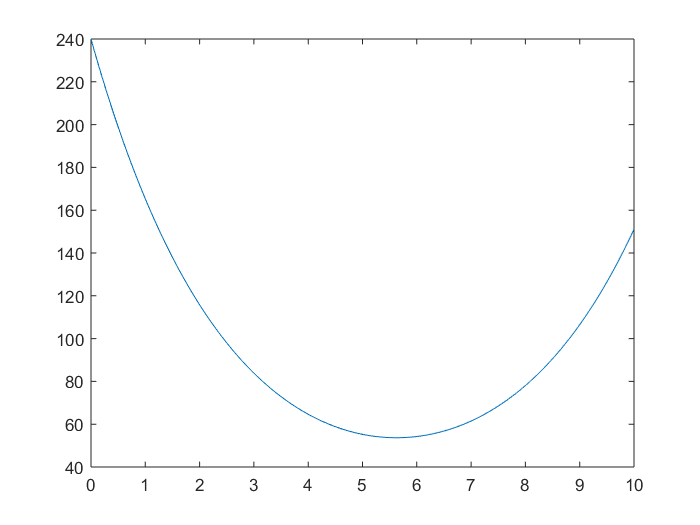

[t,y] = ivps(f,a,y0,h,b,'rk4');
plot(t,y(1,:));

N=102;
a=0;
b=10;
ya=240;
yb=150;
y= difeFinitas(a,b,ya,yb,N);

w = 	1.0e+02 *

   1.969482951518007   1.616192957305911   1.326276865938866   1.088366533455807   0.893133057494886   0.732920973848243   0.601448071609236   0.493559056111108   0.405023400327169   0.332369458113553   0.272748334569226   0.223822175619321   0.183672496450587   0.150724954188062   0.123687615011040   0.101500295048254   0.083292988615446   0.068351753689958   0.056090716928963   0.046029100496522   0.037772369879061   0.030996763460367   0.025436597232257   0.020873846835232   0.017129598421748   0.014057033114694   0.011535669968789   0.009466641690791   0.007768817870818   0.006375623709537   0.005232429497656   0.004294408484388   0.003524779137992   0.002893362874157   0.002375400698122   0.001950582358893   0.001602249946883   0.001316744706596   0.001082871451667   0.000891459580981   0.000735003482514   0.000607368224454   0.000503548993234   0.000419474845563   0.000351849079249   0.000298019963431   0.000255876759324   0.000223766954270   0.000200431463666   0

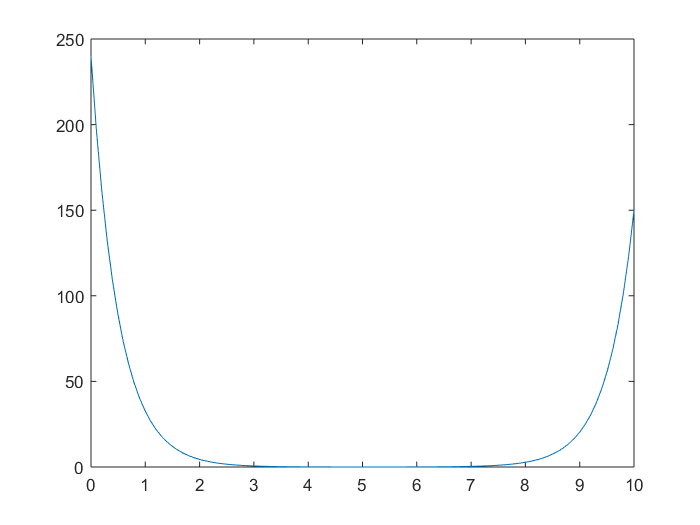

t=0:h:10;
plot(t,y);